## (a)

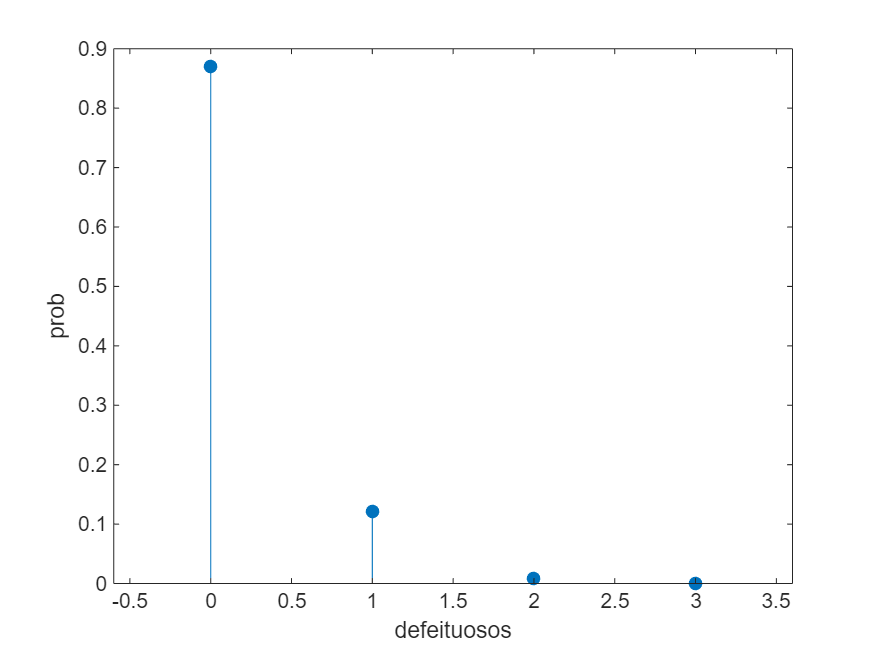

N=10000;
p1=0.002;
p2=0.005;
pa=0.01;
n=8;

def=zeros(1,N);

for i = 1:N
    lanc1 = rand(n,1)<p1;
    lanc2 = rand(n,1)<p2;
    lanca = rand(n,1)<pa;
    def(i) = sum(lanc1)+sum(lanc2)+sum(lanca);
end

x = 0:max(def);
pX = histcounts(def,[x,max(x)+1]);
pX=pX/10000;

figure;
stem(x,pX,"filled");
xlabel("defeituosos");
ylabel("prob");

## (b)

prob = sum(pX(3:end))

prob = 0.0088

## (c)

esp = sum(x .* pX)

esp = 0.1393

var = sum((x-esp).^2 .* pX)

var = 0.1387

desvio = sqrt(var)

desvio = 0.3724

## (d)

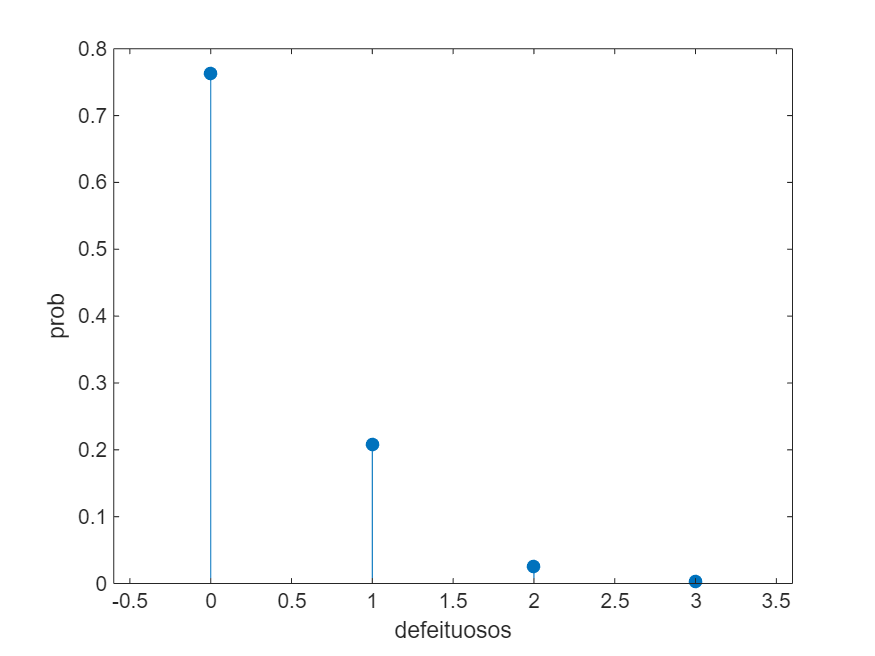

N=10000;
p1=0.002;
p2=0.005;
pa=0.01;
n=16;

def=zeros(1,N);

for i = 1:N
    lanc1 = rand(n,1)<p1;
    lanc2 = rand(n,1)<p2;
    lanca = rand(n,1)<pa;
    def(i) = sum(lanc1)+sum(lanc2)+sum(lanca);
end

x = 0:max(def);
pX = histcounts(def,[x,max(x)+1]);
pX=pX/10000;

figure;
stem(x,pX,"filled");
xlabel("defeituosos");
ylabel("prob");

esp = sum(x .* pX)

esp = 0.2676

var = sum((x-esp).^2 .* pX)

var = 0.2634

desvio = sqrt(var)

desvio = 0.5132

%% maior numero de brinquedos, maior prob de haver defeitos, obviamente a variancia e o desvio padrao tambem aumentam com o aumento de n (numero de brinquedos)